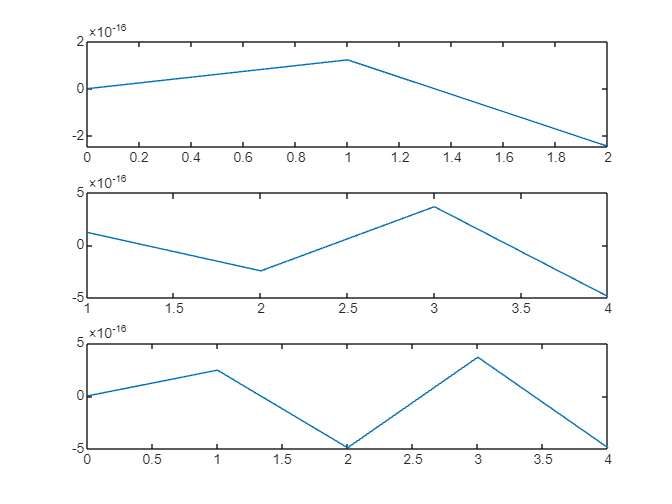

clc ;
clear all;
close all;

mint1=input("enter the min range :");
stept1=input("enter the step range :");
maxt1=input("enter the max range :");

t1=mint1:stept1:maxt1;

a1=input("enter the amplitude :");
f1=input("enter the frequency :");

[y1]=sinwv(a1,f1,t1);

subplot(3,1,1);
stem(t1,y1);

mint0=input("enter the min range :");
stept0=input("enter the step range :");
maxt0=input("enter the max range :");
t0=mint0:stept0:maxt0;

a0=input("enter the amplitude :");
f0=input("enter the frequency :");

[y0]=sinwv(a0,f0,t0);

subplot(3,1,2);
stem(t0,y0);


lb=min(mint0,mint1);
sb=min(stept1,stept0);
ub=max(maxt0,maxt1);

t3=lb:sb:ub;

y2=[];
temp=1;
for i=1:length(t3)
    if(t3(i)<mint1 || t3(i)>maxt1)
        y2=[y2 0];
    else
        y2=[y2 y1(temp)];
        temp=temp+1;
    end
end

y4=[];
temp=1;
for i=1:length(t3)
    if(t3(i)<mint0 || t3(i)>maxt0)
        y4=[y4 0];
    else
        y4=[y4 y0(temp)];
        temp=temp+1;
    end
end

y3=y4+y2;

subplot(3,1,3);
stem(t3,y3);